# （1-4节）Figure窗口管理（大小、位置调整与保存、命名等）

clc;clear;close all;

### 创建新窗口、设置标题

（下面一行的内容，粘贴到命令行窗口单独运行，即可弹出绘图窗口）

figure;           % 创建新图窗
f = figure;
f.Name = '我的图像窗口';     % 设置标题
f.NumberTitle = 'off';        % 不显示“Figure 1”等编号

### 调整窗口大小与位置

设置窗口的像素位置：

（下面一行的内容，粘贴到命令行窗口单独运行，即可弹出绘图窗口）

figure;
f = figure;
f.Position = [100, 100, 800, 600];  % 设置窗口位置和尺寸

括号里面的元素：[left, bottom, width, height]

## 图窗背景与外观

### 设置背景颜色

（下面一行的内容，粘贴到命令行窗口单独运行，即可弹出绘图窗口）

figure;
f = figure;
f.Color = [1 0 0];  % 红色背景

运行结果：

（下面一行的内容，粘贴到命令行窗口单独运行，即可弹出绘图窗口）

figure;
f = figure;
f.Color = [1 1 0];  % 黄色背景

## 导出与打印设置

### 控制图像导出大小

f.PaperPositionMode = 'auto';

### 保存高质量图片

print(f, 'output.png', '-dpng', '-r300');  % 300 DPI 输出

## 其他命令

### 添加标签：

f.Tag = 'MyCustomFigure';  % 便于在脚本中查找该图窗

### 子图绘制

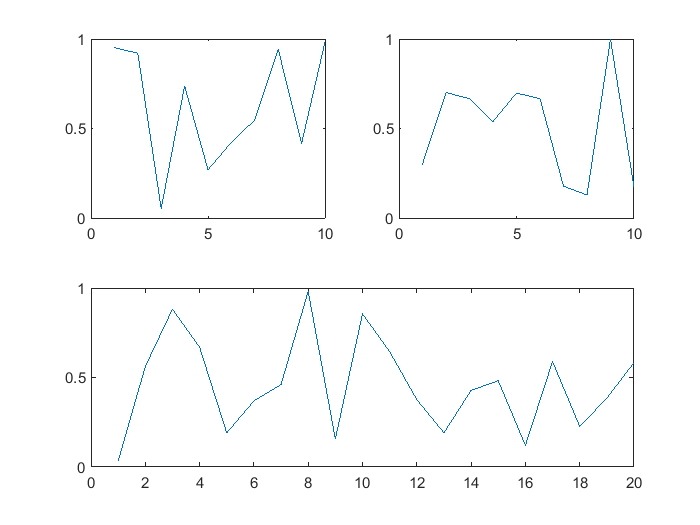

figure;
subplot(2,2,1); 
plot(rand(10,1));
subplot(2,2,2); 
plot(rand(10,1));
subplot(2,2,[3,4]);
plot(rand(20,1));

文中提到的**常用 figure 设置的模板函数**见文件夹的另外两个文件，使用例程如下（下面一行的内容，粘贴到命令行窗口单独运行，即可弹出绘图窗口）：

f = init_figure(10, 'test_10', 'Position', [0,10,300,400], 'Background', [0.2 0.3 0.4])